# MATLAB大作业（COVID-19疫情数据的简要统计分析与预测）

王逸扬（19300180016）、杨耕智（19300180112）

项目的完整内容请参见[`https://github.com/maix00/StatisticsAnalysis`](https://github.com/maix00/StatisticsAnalysis).

clear; clc;
format long
path_country = './data/COVID19/country.csv';
path_daily = './data/COVID19/daily_info.csv';
daily_SA = StatisticsAnalysis( ...
    'TablePath', path_daily, ...
    'SelectTableOptions', { 'location', 'France' } ...
    );
T = daily_SA.Table;

### Chapter 4: 长期性分析（自相关分析与周期性特征）

#### 4.1 随机性与平稳性检验

% 非随机性检验
[h0,pValue0,stat0,cValue0] = lbqtest(T.new_cases)

h0 = logical
   1

pValue0 =      0

stat0 =      8.700992803087869e+03

cValue0 =   31.410432844230918

% 对全部数据进行adftest平稳性检验
[h1,pValue1,stat1,cValue1] = adftest(T.new_cases) % 显示通过了检验

h1 = logical
   1

pValue1 =      1.000000000000000e-03

stat1 =   -7.754152935062784

cValue1 =   -1.941409000000000

% 对部分数据进行adftest平稳性检验
[h2,pValue2,stat2,cValue2] = adftest(T(250:300,:).new_cases) % 显示未通过检验

h2 = logical
   0

pValue2 =    0.068460604969584

stat2 =   -1.799891995605404

cValue2 =   -1.946700000000000

% pptest 平稳性检验
[h3,pValue3,stat3,cValue3] = pptest(T.new_cases)

h3 = logical
   1

pValue3 =      1.000000000000000e-03

stat3 =   -7.754152935062784

cValue3 =   -1.941409000000000

% test 平稳性检验
[h4,pValue4,stat4,cValue4] = kpsstest(T.new_cases)

h4 = logical
   1

pValue4 =    0.010000000000000

stat4 =    3.615112681807435

cValue4 =    0.146000000000000

#### 4.2 自相关分析

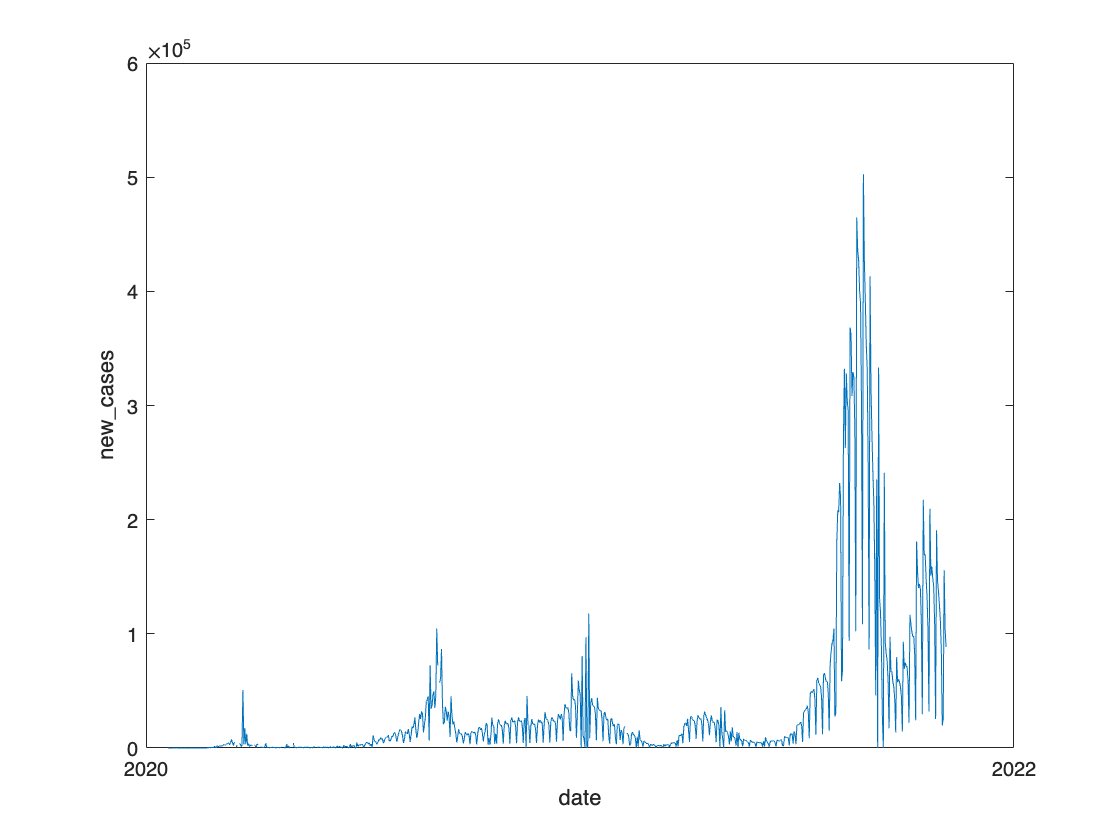

daily = daily_SA.TimeTable;
figure(1); plot(daily, 'new_cases'); datetick x; ylabel('new\_cases'); hold off

[ACF, Lags, Bounds] = autocorr(daily(200:600,:).new_cases, 398, 3)

ACF =    1.000000000000000
   0.424027920939860
   0.392487633350025
   0.514002522547414
   0.503103436332444
   0.396793545558874
   0.454226740353550
   0.617535800535406
   0.391761045981285
   0.381431442020441


Lags =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


Bounds =    0.148377680617238
  -0.148377680617238


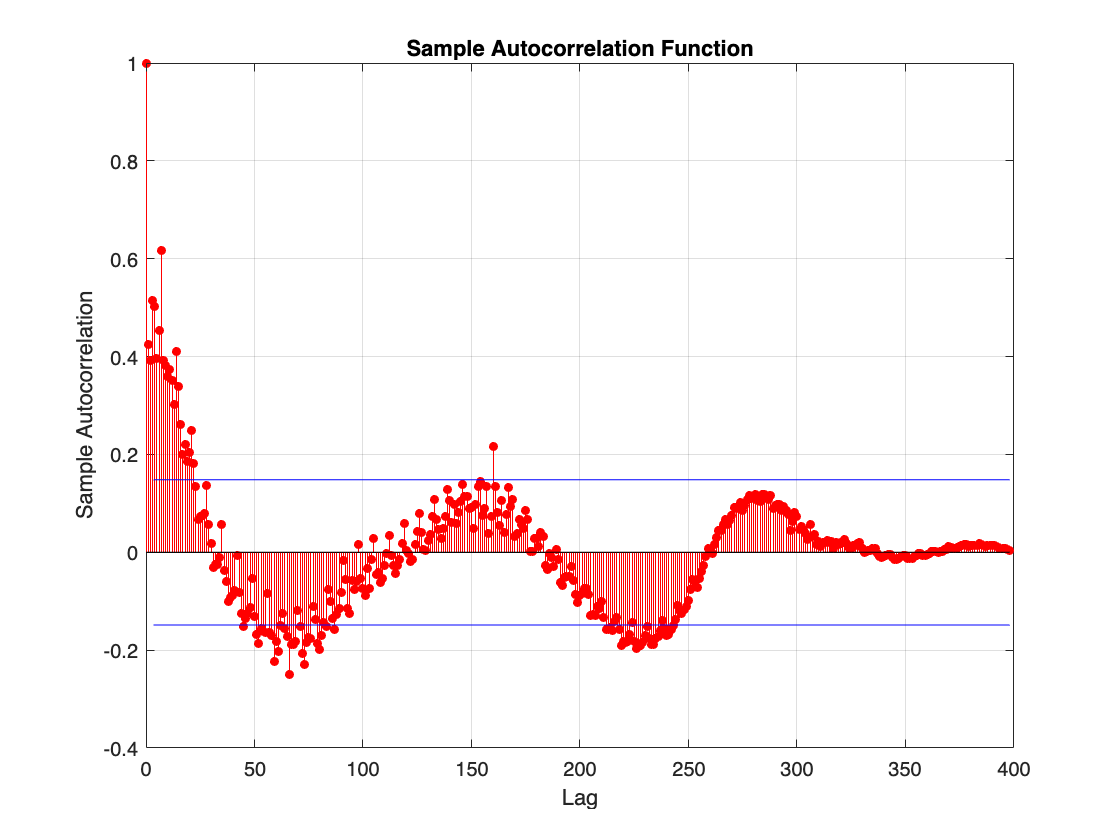

autocorr(daily(200:600,:).new_cases, 398, 3);

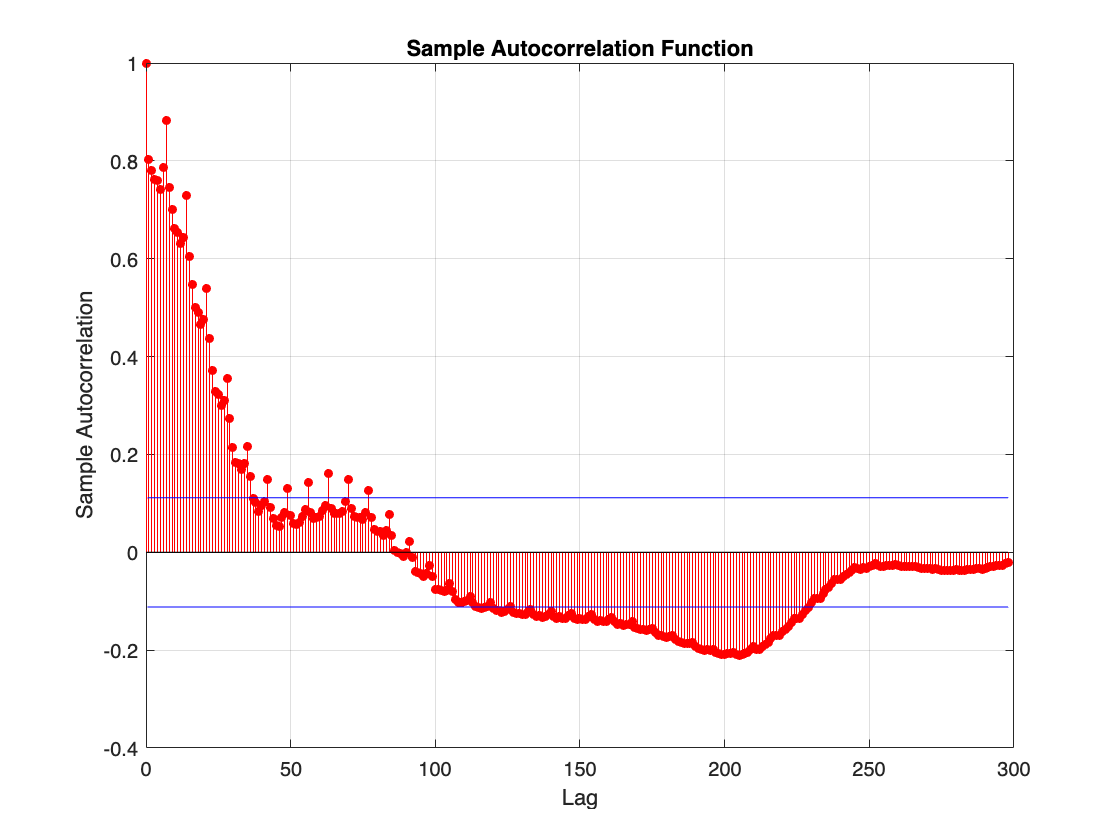

autocorr(daily(500:end,:).new_cases, 298);

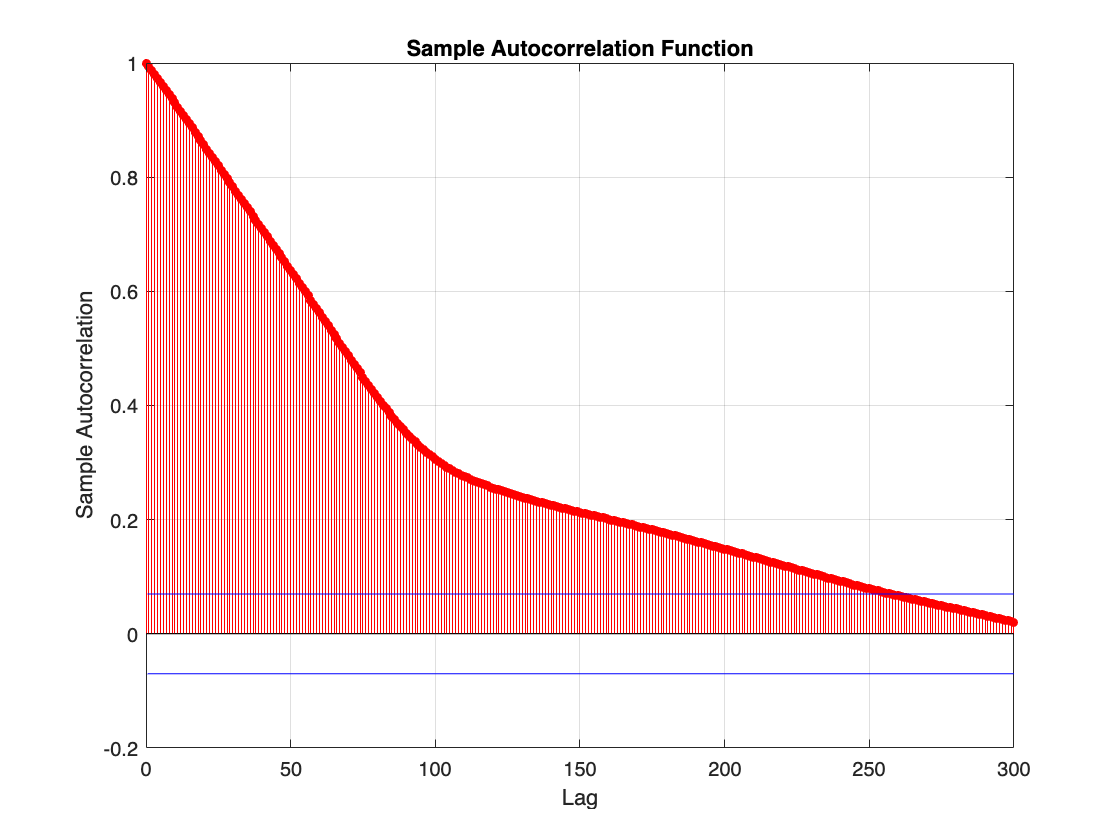

autocorr(daily.total_cases, 300); % 累积量自然都是正相关

% 手动计算Q统计量与P统计量
C = [Lags, ACF];
len = length(daily.new_cases);
lenA = length(ACF);
q = zeros(lenA - 1, 1);
for i = 2: lenA
    q(i-1) = len * (len + 2) * (ACF(i).^2) ./ (len - i + 1);
end
Q = cumsum(q);
Sig = zeros(lenA - 1, 1);
for j = 1: lenA - 1
    Sig(j) = 2 * chi2pdf(Q(j), j);
end
R = C(2: lenA, :);
RQP = [R, Q, Sig];

#### 4.3 偏自回归分析

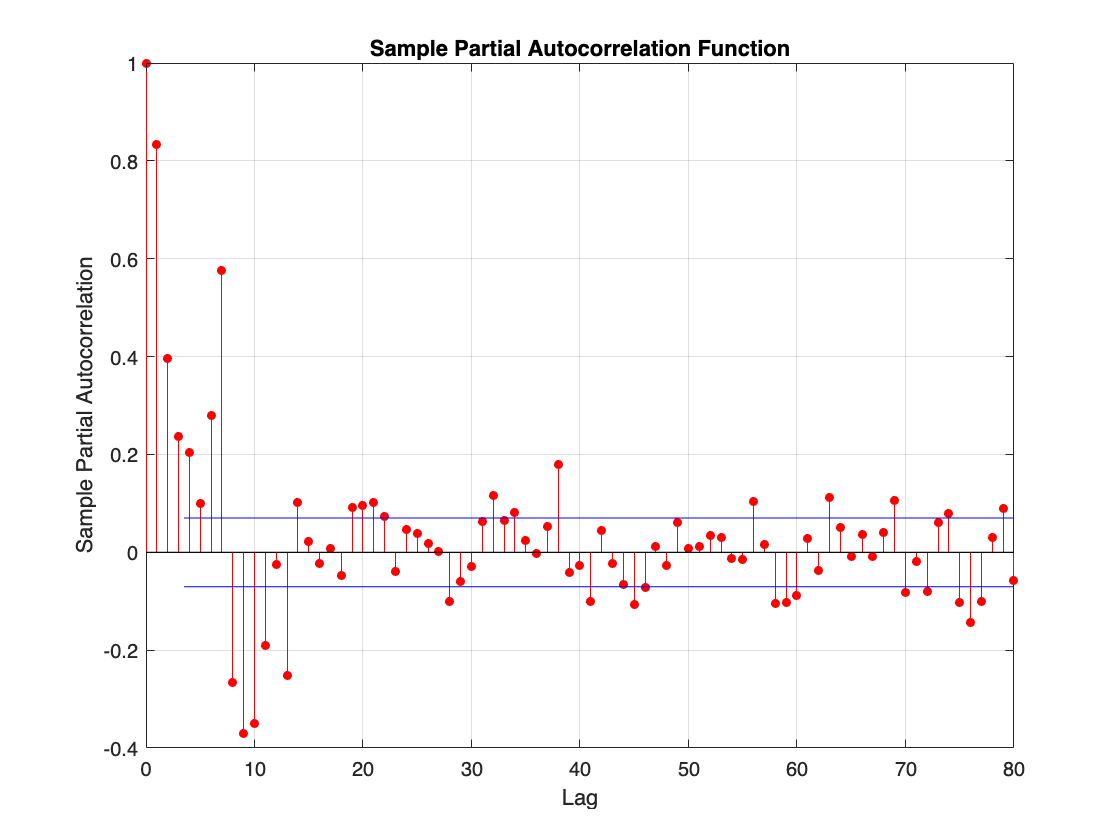

[PACF, Lags, Bounds] = parcorr(daily.new_cases, 200, 3);
parcorr(daily.new_cases, 80, 3);

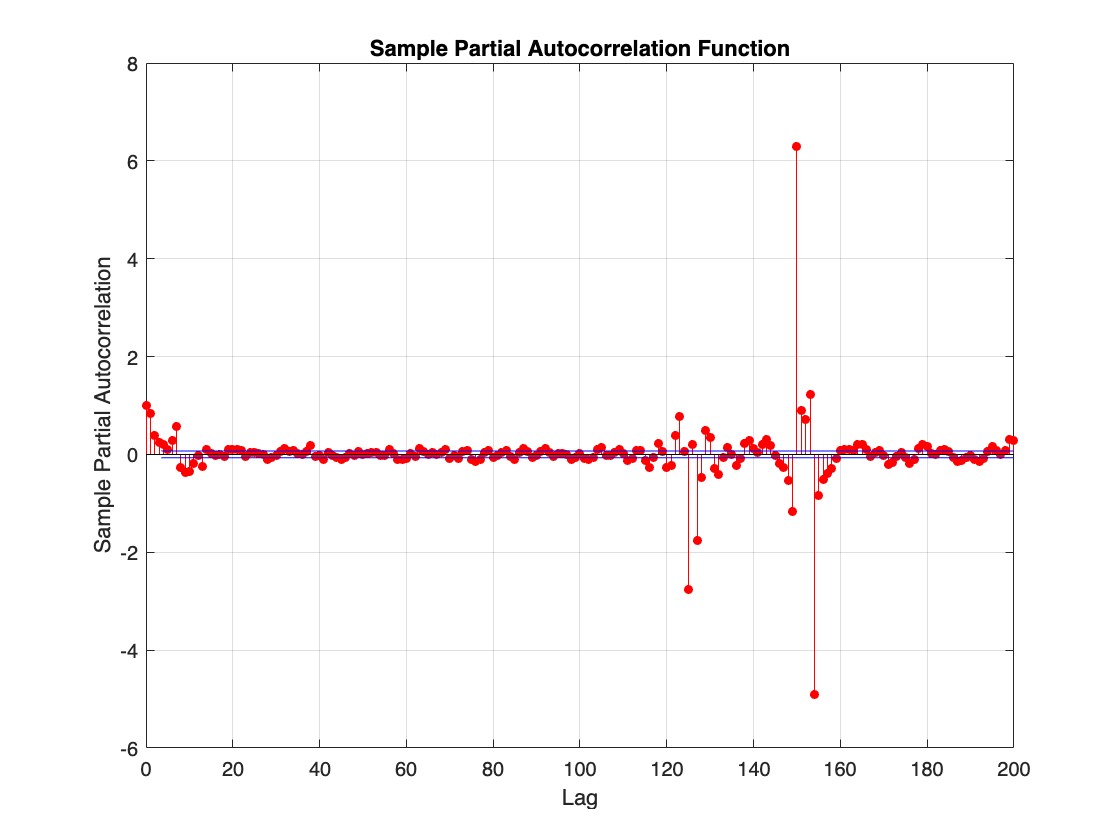

parcorr(daily.new_cases, 200, 3);

### 附录1：HP滤波器产生的影响

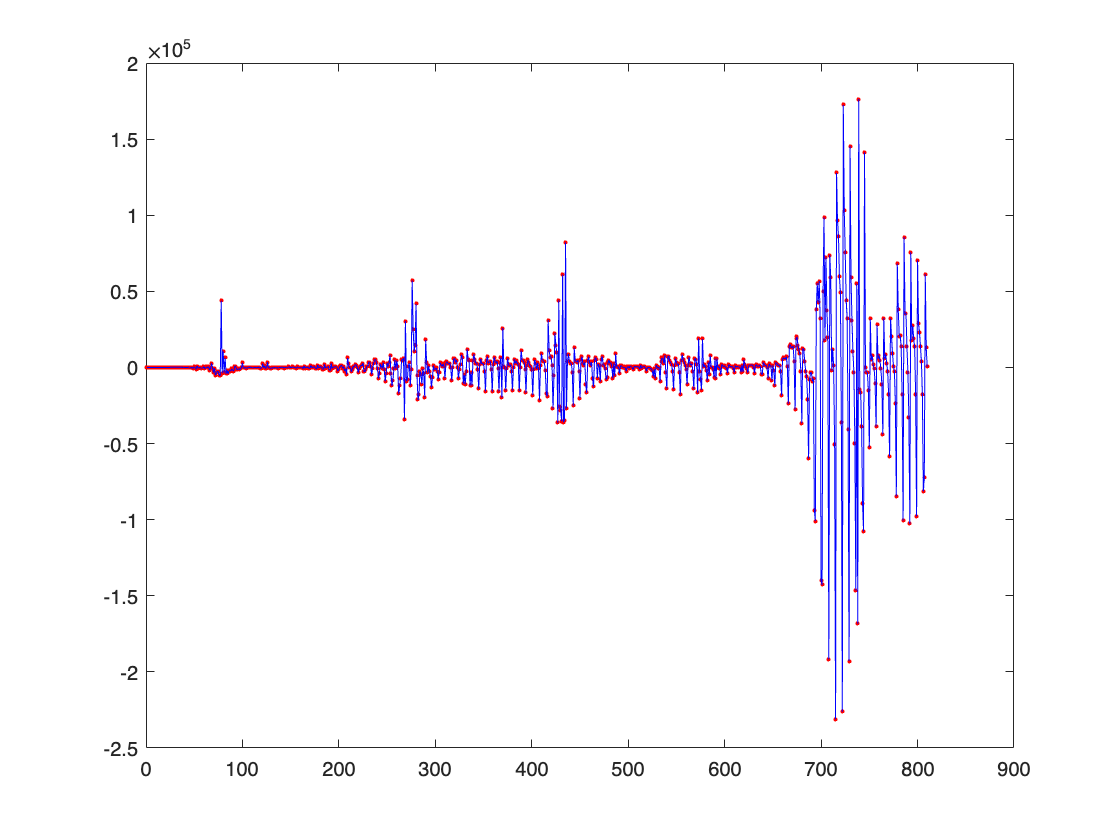

[Trend, Cyclical] = hpfilter(T, 'DataVariables', {'new_cases'});
figure(1); plot(Cyclical.new_cases, 'r.'); hold on
plot(Cyclical.new_cases, 'b-'); hold off

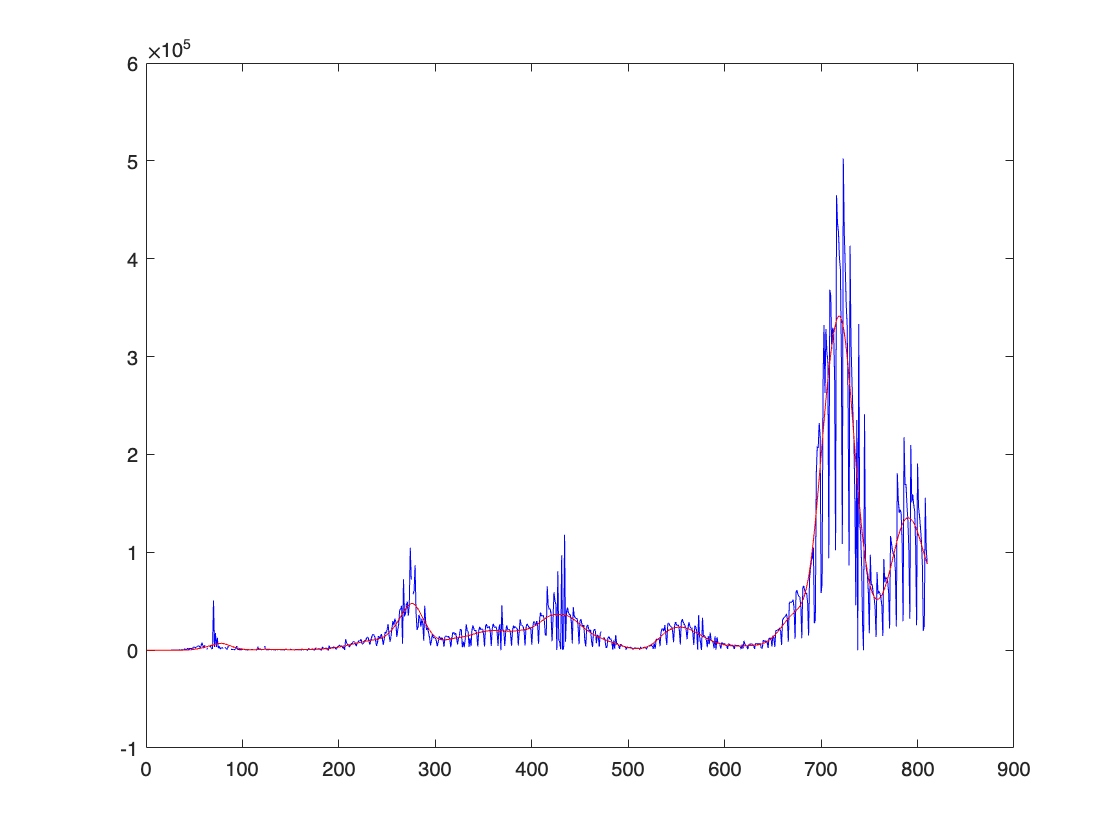

figure(2);
plot(daily(11:end,:).new_cases, 'b-'); hold on
plot(Trend.new_cases, 'r-'); hold off

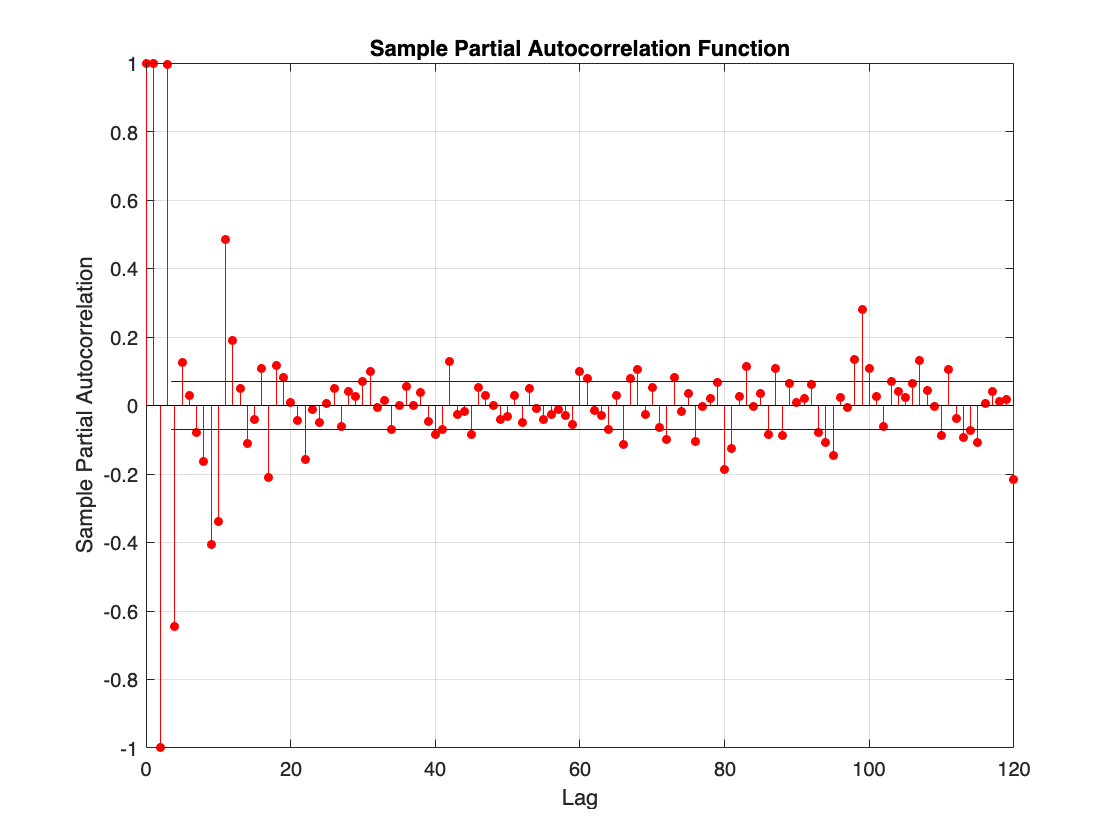

parcorr(Trend.new_cases, 120, 3);